# Use a Python Pre-Trained Audio AI System in MATLAB

## This Example Shows How to:

- Execute a pretrained Python speech command recognition system in MATLAB.

- Convert the Python system to a MATLAB system where Python is not required.

- Use the MATLAB speech command recognition system in Simulink.

- Generate C code from the MATLAB or Simulink system, and deploy it to a Raspberry Pi device.

## Overview

There are different options for accessing deep learning models trained in non-MATLAB frameworks within MATLAB, including:

- Co-executing models from other frameworks with MATLAB.

- Converting models from other frameworks into MATLAB.

This example provides an overview of both approaches using a Python speech command recognition system as a starting point. In addition to a pretrained convolutional network, the system also includes audio feature extraction. You access both the neural network and the feature extraction in MATLAB.

You use the converted command recognition system in both MATLAB and Simulink. You also learn how to generate C code from the system and deploy it to a Raspberry Pi device.

## Requirements

- [MATLAB®](https://www.mathworks.com/) R2021b or later

- [Deep Learning Toolbox™](https://www.mathworks.com/products/deep-learning.html)

- [Audio Toolbox™](https://www.mathworks.com/products/audio.html)

The Python code uses the following packages:

- Librosa™ version 0.8.1

- PyTorch™ version 1.10.2

## System Description 

In this example, you start with a deep learning speech command recognition system that was trained in Python.

The system recognizes the following commands:

- "yes"

- "no"

- "up"

- "down"

- "left"

- "right"

- "on"

- "off"

- "stop"

- "go"

The system is comprised of a convolutional neural network. The network accepts auditory spectrograms as an input. Auditory spectrograms are time-frequency representations of speech. They are derived from the raw (time-domain) audio signal.

For the training workflow, a supervized learning approach is followed, where auditory spectrograms labeled with commands are fed to the network.

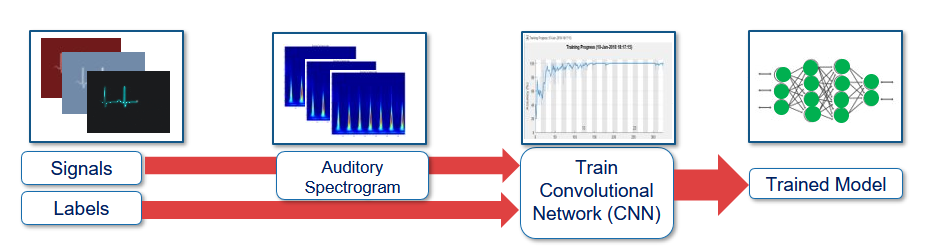

The following were used to train the command recognition system:

- **PyTorch** to design and train the model.

- **Librosa** to perform feature extraction (auditory spectrogram computation).

You perform speech recognition in Python by first extracting an auditory spectrogram from an audio signal, and then feeding the spectrogram to the trained convolutional network.

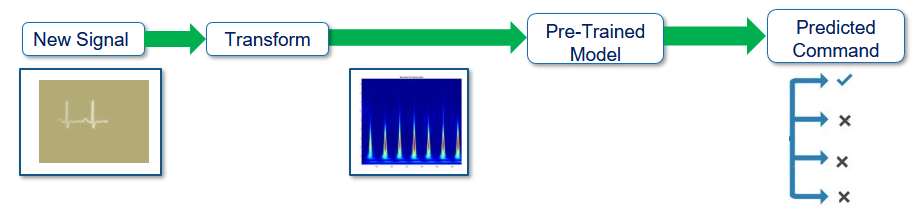

## Using the Python System in MATLAB: Two Approaches

You can use the Python system in MATLAB with co-execution. This approach allows you to access variables computed by running Python code in MATLAB, including the predicted speech command, the network activations, and the computed auditory spectrogram. This approach enables you to test the network in MATLAB (for example, by plotting the results, or using them to compute quality metrics implemented in MATLAB).

Co-execution does not address all workflows. For example, if you want to leverage MATLAB's C code generation capabilities to deploy the system to an embedded target, you must first convert the Python system to a MATLAB version. To do this, you translate both feature extraction and the neural network to MATLAB. You then generate code from the MATLAB command recognition system.

You go through both approaches in the next sections.

## Supporting Python Files

The deep learning model is defined in [`speechCommandModel.py`](matlab:open('./PythonCode\speechCommandModel.py'))`.`

The script [`InferSpeechCommands.py`](matlab:open('./PythonCode\InferSpeechCommands.py')) performs command recongition using the pretrained system.

## Running the System in MATLAB

First, add the required files to the path.

addpath("HelperFiles")
addpath("samples")

For more information about this functionality, see [Call Python from MATLAB](https://www.mathworks.com/help/matlab/call-python-libraries.html) in the documentation.. In this example, we use [`pyrunfile`](https://www.mathworks.com/help/matlab/ref/pyrunfile.html?searchHighlight=pyrunfile&s_tid=srchtitle_pyrunfile_1) to achieve this. 

The Python script [`InferSpeechCommands.py`](matlab:open('./PythonCode\InferSpeechCommands.py')) performs speech command recognition. Instead of defining the sample audio file path in Python, you define it in MATLAB, and pass it to Python. Note that `filename` corresponds to a variable name in the Python script.

Execute Python inference in MATLAB. The Python script prints out the recognized keyword.

command = fullfile(pwd,"samples","yes.flac");
cd("PythonCode")
pyrunfile("InferSpeechCommands.py",filename=command)

Recognized command: yes


It is also possible to return Python variables to MATLAB. Call `InferSpeechCommands `again, and return the following:

- The mel spectrogram (computed by **Librosa**).

- The network activations.

- The parameter-value pairs passed to Librosa's mel spectrogram function.

[LibrosaMelSpectrogram,PyTorchActivations,MelSpectrogramArgs] = pyrunfile("InferSpeechCommands.py",...
                                                                ["mel_spectrogram","z","args"],filename=command);

Recognized command: yes


cd ..

Notice that the output arguments are Python datatypes:

PyTorchActivations

PyTorchActivations =   Python ndarray:

    0.1500    8.0174    0.3631  -10.5605   -1.4616    1.1130  -10.2887  -11.9670   -4.6792   -2.9368   -3.0234

    Use details function to view the properties of the Python object.

    Use single function to convert to a MATLAB array.


Convert them to MATLAB datatypes:

PyTorchActivations = double(PyTorchActivations)

PyTorchActivations =     0.1500    8.0174    0.3631  -10.5605   -1.4616    1.1130  -10.2887  -11.9670   -4.6792   -2.9368   -3.0234


Convert the mel spectrogram to a MATLAB matrix as well.

LibrosaMelSpectrogram = double(LibrosaMelSpectrogram);
size(LibrosaMelSpectrogram)

ans =     98    50


## Converting the Python Speech Command Recognition System to a MATLAB System

Executing Python code in MATLAB is useful for many workflows, but it is not sufficient for certain scenarios. In this example, you want to leverage MATLAB's code generation abilities to deploy your speech command recognition system to an embedded target. For this task, you need access to a full MATLAB version of the speech command recognition system.

Recall that the system is comprised of two components (feature extraction and network inference). The example explains how to convert each from Python to MATLAB.

### Converting the Network to MATLAB

To import the ONNX network to MATLAB, use [importONNXNetwork](https://www.mathworks.com/help/deeplearning/ref/importonnxnetwork.html). Note that we saved the trained network to an Open Neural Network Exchange (ONNX) format for you.

onnxFile = "cmdRecognitionPyTorch.onnx";

Import the network to MATLAB

net = importONNXNetwork(onnxFile)

net =   DAGNetwork with properties:

         Layers: [19×1 nnet.cnn.layer.Layer]
    Connections: [18×2 table]
     InputNames: {'input'}
    OutputNames: {'RegressionLayer_output'}


### Verify The Network Activations

Verify that the MATLAB network gives the same activations as the PyTorch network for the same mel spectrogram input. Use the spectrogram you returned from the Python inference script.

MATLABActivations = predict(net,LibrosaMelSpectrogram);

Compare MATLAB and PyTorch activations.

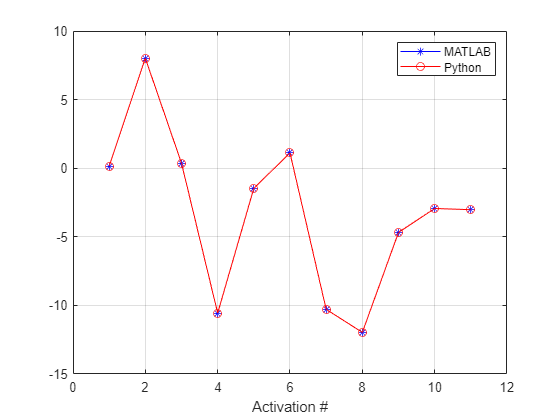

figure
plot(MATLABActivations,"b*-")
hold on
grid on
plot(PyTorchActivations,"ro-")
xlabel("Activation #")
legend("MATLAB", "Python")

## Converting Feature Extraction to MATLAB

You now have access to a MATLAB implementation of the pretrained network.

You now translate the Librosa feature extraction to its MATLAB equivalent.

Feature extraction is part of the speech command recognition system. Access to a MATLAB version of this feature extraction will enable you to leverage advanced MATLAB functionality (e.g. deploy the entire system to an embedded target, including feature extraction).

### Mel Spectrogram Computation in MATLAB

`audioFeatureExtractor `in Audio Toolbox supports mel spectrogram computations. 

But how do we go about setting it to ensure we get the exact same mel spectrogram as Librosa?

[y, fs] = audioread(command);
afe = audioFeatureExtractor(melSpectrum=true, SampleRate = fs);
MATLABMelSpectrogram = extract(afe,y);
size(MATLABMelSpectrogram)

ans =     30    32


Compare to the Librosa spectrogram. Notice that the sizes do not match by default.

size(LibrosaMelSpectrogram)

ans =     98    50


### Librosa-to-Audio Toolbox Conversion 

Matching MATLAB and Librosa feature extraction by setting parameter-value pairs on `audioFeatureExtractor` is possible, but it can be a tedious and time-consuming task.

Simplify the process by using the helper function [`librosaToAudioToolbox`](matlab:open('./HelperFiles\librosaToAudioToolbox.m')). This function takes the parameter-value pair arguments used in Librosa's mel spectrogram function, and automatically maps them to an equivalent `audioFeatureExtractor` object.

afe = librosaToAudioToolbox("melSpectrogram", MelSpectrogramArgs)

afe =     'afe = audioFeatureExtractor(SampleRate=16000.000000,Window=hann(512,"periodic"),...
     OverlapLength=352,FFTLength=512,melSpectrum=true);
     
     setExtractorParameters(afe,"melSpectrum",SpectrumType="power",...
                              FilterBankDesignDomain="linear",...
                              FilterBankNormalization="bandwidth",...
                              WindowNormalization=false,...
                              NumBands=50,...);
                              FrequencyRange=[0.000000 8000.000000]);
     
     S = extract(afe,y);'


Compute the log mel spectrogram based on this object.

MATLABMelSpectrogram = extract(afe,y);
MATLABMelSpectrogram = log10(MATLABMelSpectrogram + 1e-6);

Compare to the Librosa mel spectrogram.

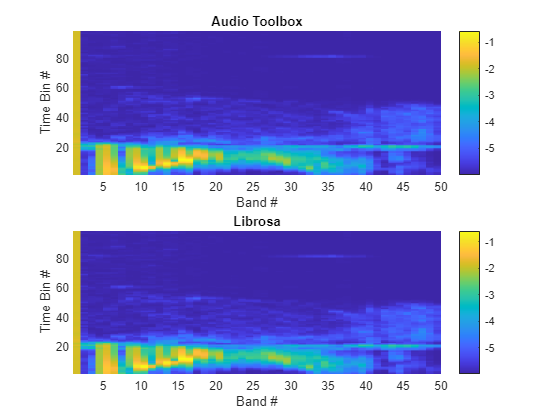

figure
subplot(2,1,1)
smag = MATLABMelSpectrogram;
T = 1:size(MATLABMelSpectrogram,1);
F = 1:size(MATLABMelSpectrogram,2);
pcolor(F,T, smag)
ylabel("Time Bin #")
xlabel("Band #")
shading flat
colorbar
title("Audio Toolbox")
subplot(2,1,2)
smag = LibrosaMelSpectrogram;
pcolor(F,T, smag)
ylabel("Time Bin #")
xlabel("Band #")
shading flat
colorbar
title("Librosa")

The two spectrograms look identical. Compute an error metric to make sure.

norm(MATLABMelSpectrogram(:)-LibrosaMelSpectrogram(:))

ans = 9.2636e-06

## Generate MATLAB Code for Feature Extraction

You now have access to an `audioFeatureExtractor `that matches Librosa, but it would be nice to know how to exactly set that object. 

You can generate MATLAB code that instantiates and sets up `audioFeatureExtractor `by using the "code" option on `librosaToAudioToolbox`.

code = librosaToAudioToolbox("melSpectrogram", MelSpectrogramArgs,"code")

code =     'afe = audioFeatureExtractor(SampleRate=16000.000000,Window=hann(512,"periodic"),...
     OverlapLength=352,FFTLength=512,melSpectrum=true);
     
     setExtractorParameters(afe,"melSpectrum",SpectrumType="power",...
                              FilterBankDesignDomain="linear",...
                              FilterBankNormalization="bandwidth",...
                              WindowNormalization=false,...
                              NumBands=50,...);
                              FrequencyRange=[0.000000 8000.000000]);
     
     S = extract(afe,y);'


## Speech Command Recognition in MATLAB

You are now ready to perform speech command recognition entirely in MATLAB.

Copy and paste the feature extraction code from above.

afe = audioFeatureExtractor(SampleRate=16000.000000,Window=hann(512,"periodic"),...
     OverlapLength=352,FFTLength=512,melSpectrum=true);
     
setExtractorParameters(afe,"melSpectrum",SpectrumType="power",...
                            FilterBankDesignDomain="linear",...
                            FilterBankNormalization="bandwidth",...
                            WindowNormalization=false,...
                            NumBands=50,...
                            FrequencyRange=[0 8000]);  

Compute the mel spectrogram.

S = extract(afe,y);
S = log10(S+1e-6);

Compute the network activation using the MATLAB Deep Learning network. 

activations = predict(net,S)

activations = 1×11 single row vector
    0.1500    8.0174    0.3631  -10.5605   -1.4616    1.1130  -10.2887  -11.9670   -4.6792   -2.9368   -3.0234


Deduce the spoken command.

CLASSES = ["unknown" " yes" " no" " up" " down" " left" " right" " on" " off" " stop" "go"];
[~,ind] = max(activations);
fprintf("Recognized command: %s\n",CLASSES(ind))

Recognized command:  yes


## Speech Command Recognition in Simulink

You successfully implemented a pure MATLAB version of speech command recognition. 

You can also use this system in Simulink.

### Using the Deep Learning Model in Simulink

You can use the deep learning network in Simulink using the [Predict](https://www.mathworks.com/help/deeplearning/ref/predict.html) block.

Save the network to a MAT file. You can point the Predict block to this MAT file to use it in Simulink.

save net.mat net

### Implementing Feature Extraction for Simulink

What about feature extraction in Simulink? Use the "block" switch on `librosaToAudioToolbox` to generate an equivalent mel Spectrogram block. This library block ships with Audio Toolbox. You need R2022A or later to access this block.

librosaToAudioToolbox("melSpectrogram", MelSpectrogramArgs,"block");

### Speech Command Recognition System in Simulink

The following model uses the two blocks discussed above to perform speech command recognition in Simulink.

open_system("speechCommandRecognition")

Run the model to observe the network output activations.

## Deploying The System to an Embedded Target

The Simulink and MATLAB versions highlighted above both support C code generation and deployment to an embedded target. 

For more information on how to deploy the MATLAB version, see the following examples:

- [Speech Command Recognition Code Generation with Intel MKL-DNN](https://www.mathworks.com/help/deeplearning/ug/speech-command-recognition-code-generation-with-intel-mkl-dnn.html)

-  [Speech Command Recognition Code Generation on Raspberry Pi](https://www.mathworks.com/help/deeplearning/ug/speech-command-recognition-code-generation-on-raspberry-pi.html)

For more information on how to deploy the Simulink version, see the following examples:

- [Speech Command Recognition Code Generation with Intel MKL-DNN Using Simulink](https://www.mathworks.com/help/audio/ug/speech-command-recognition-code-generation-with-intel-mkl-dnn-using-simulink.html)

- [Speech Command Recognition on Raspberry Pi Using Simulink](https://www.mathworks.com/help/audio/ug/speech-command-recognition-on-raspberry-pi-using-simulink.html)

*Copyright 2022 The MathWorks, Inc.*